%% Bucher Mobile DCU
clear;
clc;

%% basic params
Ts        = 1e-4;
Tfinal    = 6.0;

% motor electrical
p         = 3;
Rs        = 20e-3;
Ld        = 300e-6;
Lq        = 300e-6;
psi_f     = 0.08;

% current / torque limits
Imax      = 150;
diq_slew  = 1000;
did_slew  = 8000;
Tmax_reg  = 150;
T_rated   = 100;
T_fac     = 1.5;

% speed limits
w_max     = 800;
acc_max   = 1500;
dec_max   = -1500;

% DC link
Vdc_nom   = 320;
Vdc_max   = 350;
Vdc_min   = 260;
Cdc       = 2.2e-3;
Rsrc      = 0.5;
dv_max    = 1e5;

% d/q current PI
Kp_d      = 1.0;
Ki_d      = 100.0;
Kp_q      = 1.0;
Ki_q      = 100.0;
decouple_k = 1.0;

% speed PI
Kp_w      = 0.05;
Ki_w      = 0.10;

% field weakening
FW_Kp     = 2.0e-3;
FW_Ti     = 2.0e-2;
vfac      = 0.90;
id_fac    = 0.60;
FW_on     = 1.02;
FW_off    = 0.98;

% regen (PI-based, speed to zero)
omega_regen_min = 20;
Vp_vdc          = 0.10;   % regen PI Kp (speed-based)
Tn_vdc          = 0.05;   % regen PI Ti

% mech
J         = 1e-1;
B         = 2e-2;
T_coulomb = 0.5;

% angle / resolver / observer
mode_inner       = 6;     
pos_offset       = 0.0;
pole_pairs_ratio = 1.0;   
alpha_res        = 0.02;
hv_ok            = 1;

%% scenarios -> speed torque regen
S(1) = struct('name',"Torque Mode: Spin-up to 400 rad/s", ...
    'mode', 4, 'speed_rpm', 0, ...
    'torque_cmd', [0.5 0 30], 'TL', [0.3 0 3], ...
    'T', Tfinal, 'init_omega', 0, 'init_theta', 0);

S(2) = struct('name',"Speed Mode: Hold 400 rad/s", ...
    'mode', 2, 'speed_rpm', 400*60/(2*pi), ...
    'torque_cmd', [0 0 0], 'TL', [0.3 0 3], ...
    'T', Tfinal, 'init_omega', 'continue', 'init_theta', 'continue');

S(3) = struct('name',"Regen Mode: Brake to standstill", ...
    'mode', -5, 'speed_rpm', 0, ...
    'torque_cmd', [0 0 0], 'TL', [0.3 0 0], ...
    'T', Tfinal, 'init_omega', 'continue', 'init_theta', 'continue');

%% pack params (modular)
P.Ts        = Ts;
P.p         = p;
P.Rs        = Rs;
P.Ld        = Ld;
P.Lq        = Lq;
P.psi_f     = psi_f;

P.Imax      = Imax;
P.diq_slew  = diq_slew;
P.did_slew  = did_slew;
P.Tmax_reg  = Tmax_reg;
P.T_rated   = T_rated;
P.T_fac     = T_fac;

P.w_max     = w_max;
P.acc_max   = acc_max;
P.dec_max   = dec_max;

P.Vdc_nom   = Vdc_nom;
P.Vdc_max   = Vdc_max;
P.Vdc_min   = Vdc_min;
P.Cdc       = Cdc;
P.Rsrc      = Rsrc;
P.dv_max    = dv_max;

P.Kp_d      = Kp_d;
P.Ki_d      = Ki_d;
P.Kp_q      = Kp_q;
P.Ki_q      = Ki_q;
P.Kp_w      = Kp_w;
P.Ki_w      = Ki_w;
P.decouple_k = decouple_k;

P.FW_Kp     = FW_Kp;
P.FW_Ti     = FW_Ti;
P.vfac      = vfac;
P.id_fac    = id_fac;
P.FW_on     = FW_on;
P.FW_off    = FW_off;

P.omega_regen_min = omega_regen_min;
P.Vp_vdc          = Vp_vdc;
P.Tn_vdc          = Tn_vdc;

P.J         = J;
P.B         = B;
P.T_coulomb = T_coulomb;

P.mode_inner       = mode_inner;
P.pos_offset       = pos_offset;
P.pole_pairs_ratio = pole_pairs_ratio;
P.alpha_res        = alpha_res;
P.hv_ok            = hv_ok;

%% init + run
X0 = struct('id',0,'iq',0,'omega_m',0,'theta_m',0,'vdc',Vdc_nom);
statusLast = default_status();
Runs = cell(1, numel(S));

for k = 1:numel(S)
    fprintf('Case %d: %s\n', k, S(k).name);
    Runs{k} = run_scenario(S(k), X0, statusLast, P);
    X0 = Runs{k}.final_state;
    statusLast = Runs{k}.status(end);
end

Case 1: Torque Mode: Spin-up to 400 rad/s
Case 2: Speed Mode: Hold 400 rad/s
Case 3: Regen Mode: Brake to standstill



disp('All successful');

All successful


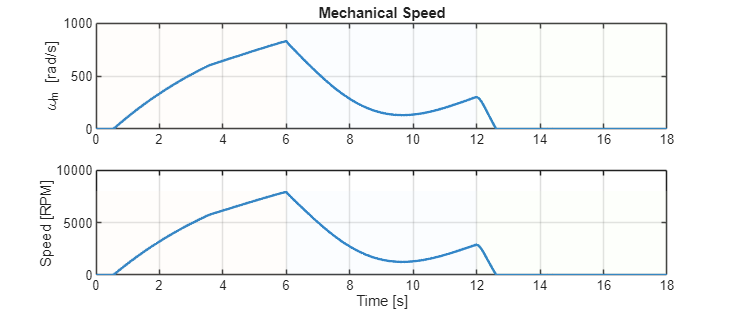


%% gather results
t_all=[]; omega_all=[]; Te_all=[]; Tcmd_all=[]; vdc_all=[]; id_all=[]; iq_all=[]; P_gen_all=[]; mode_all=[];
t_offset = 0;

for k=1:numel(Runs)
    t_all     = [t_all;     Runs{k}.t + t_offset];
    omega_all = [omega_all; Runs{k}.omega_m];
    Te_all    = [Te_all;    Runs{k}.Te];
    Tcmd_all  = [Tcmd_all;  Runs{k}.cmd_torque];
    vdc_all   = [vdc_all;   Runs{k}.vdc];
    id_all    = [id_all;    Runs{k}.id];
    iq_all    = [iq_all;    Runs{k}.iq];

    if S(k).mode == -5
        P_gen_all = [P_gen_all; max(0,-Runs{k}.P_e)];
    else
        P_gen_all = [P_gen_all; zeros(size(Runs{k}.P_e))];
    end

    mode_all  = [mode_all;  ones(size(Runs{k}.t))*S(k).mode];
    t_offset  = t_all(end);
end

%% plots
figure('Name','Speed','Position',[100 100 1000 420]);
subplot(2,1,1);
plot(t_all,omega_all,'LineWidth',1.5);
grid on;
ylabel('\omega_m [rad/s]');
title('Mechanical Speed');
add_mode_regions(t_all,mode_all);

subplot(2,1,2);
plot(t_all,omega_all*60/(2*pi),'LineWidth',1.5);
grid on;
xlabel('Time [s]');
ylabel('Speed [RPM]');
add_mode_regions(t_all,mode_all);

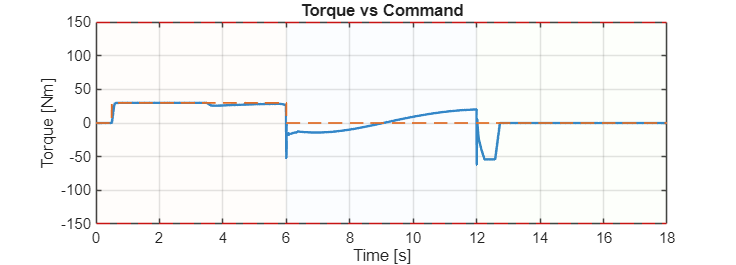


figure('Name','Torque','Position',[120 120 1000 360]);
plot(t_all,Te_all,'LineWidth',1.5); hold on; grid on;
plot(t_all,Tcmd_all,'--','LineWidth',1.1);

Tmax_plot_mot = T_fac*T_rated;   % motor-side torque limit from allowed params
yline(Tmax_plot_mot,'r--');
yline(-Tmax_reg,'r--');

xlabel('Time [s]');
ylabel('Torque [Nm]');
title('Torque vs Command');
add_mode_regions(t_all,mode_all);

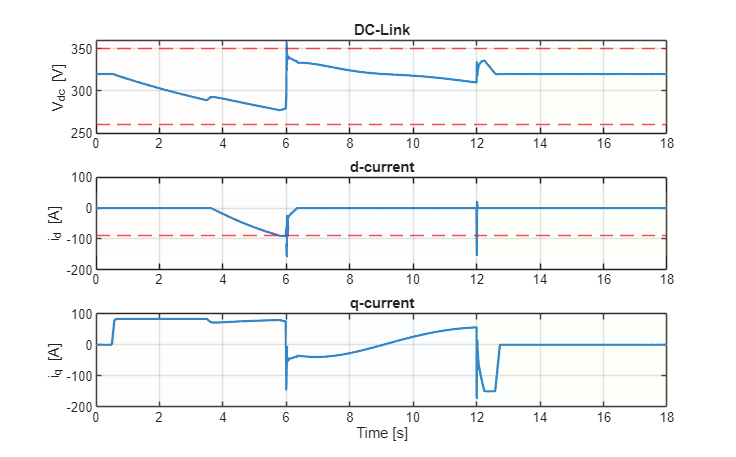


figure('Name','DC-Link & Currents','Position',[140 140 1000 620]);
subplot(3,1,1);
plot(t_all,vdc_all,'LineWidth',1.4);
grid on; hold on;
yline(Vdc_max,'r--');
yline(Vdc_min,'r--');
ylabel('V_{dc} [V]');
title('DC-Link');
add_mode_regions(t_all,mode_all);

subplot(3,1,2);
plot(t_all,id_all,'LineWidth',1.4);
grid on;
ylabel('i_d [A]');
yline(-id_fac*Imax,'r--');
title('d-current');
add_mode_regions(t_all,mode_all);

subplot(3,1,3);
plot(t_all,iq_all,'LineWidth',1.4);
grid on;
xlabel('Time [s]');
ylabel('i_q [A]');
title('q-current');
add_mode_regions(t_all,mode_all);

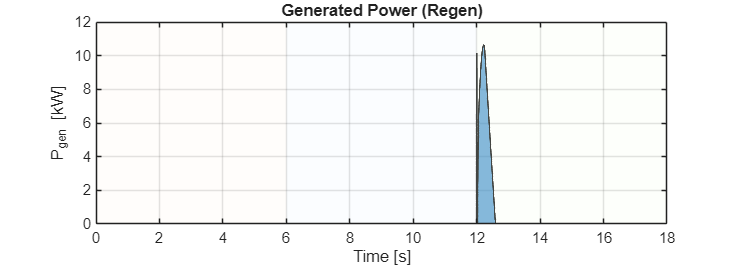


figure('Name','Regenerative Power','Position',[160 160 1000 360]);
area(t_all,P_gen_all/1000,'FaceAlpha',0.6,'LineWidth',1.0);
grid on;
xlabel('Time [s]');
ylabel('P_{gen} [kW]');
title('Generated Power (Regen)');
add_mode_regions(t_all,mode_all);


fprintf('\nRegen SUMMARY\n');


Regen SUMMARY


fprintf('Energy: %.2f kJ\n', trapz(t_all,P_gen_all)/1000);

Energy: 3.75 kJ


fprintf('Peak power: %.2f kW\n', max(P_gen_all)/1000);

Peak power: 10.63 kW



%% shaded regions
function add_mode_regions(t, modes)
    ylims = ylim;
    idx = [1; find(diff(modes)~=0)+1; numel(modes)];
    colors = containers.Map([2,4,-5], ...
        {[0.9 0.95 1], [1 0.95 0.9], [0.95 1 0.9]});
    hold on
    for i=1:numel(idx)-1
        i1 = idx(i); i2 = idx(i+1); m = modes(i1);
        if colors.isKey(m)
            patch([t(i1) t(i2) t(i2) t(i1)], ...
                  [ylims(1) ylims(1) ylims(2) ylims(2)], ...
                  colors(m), ...
                  'FaceAlpha',0.16, ...
                  'EdgeColor','none', ...
                  'HandleVisibility','off');
        end
    end
end

%% main scenario sim
function R = run_scenario(S, X0, statusPrev, P)
    Ts = P.Ts;
    Nt = floor(S.T/Ts)+1;
    t  = (0:Nt-1)'*Ts;

    id       = zeros(Nt,1);
    iq       = zeros(Nt,1);
    omega_m  = zeros(Nt,1);
    theta_m  = zeros(Nt,1);
    Te       = zeros(Nt,1);
    vdc      = zeros(Nt,1);
    vd_cmd_v = zeros(Nt,1);
    vq_cmd_v = zeros(Nt,1);
    cmd_speed  = zeros(Nt,1);
    cmd_torque = zeros(Nt,1);
    P_e      = zeros(Nt,1);
    status(Nt,1) = default_status(); %#ok<STRNU>

    if ischar(S.init_omega) && strcmp(S.init_omega,'continue')
        id_k   = X0.id;
        iq_k   = X0.iq;
        w_k    = X0.omega_m;
        th_k   = X0.theta_m;
        vdc_k  = X0.vdc;
    else
        id_k   = 0;
        iq_k   = 0;
        w_k    = S.init_omega;
        th_k   = S.init_theta;
        vdc_k  = P.Vdc_nom;
    end

    M  = init_mem();
    st = statusPrev;
    sat_mode_prev = 0;
    spd_ref = S.speed_rpm*2*pi/60;

    for n = 1:Nt
        tn = t(n);

        Tcmd = step3(tn, S.torque_cmd);
        TL   = step3(tn, S.TL);
        cmd_torque(n) = Tcmd;

        if S.mode == 2
            cmd_speed(n) = spd_ref;
        end

        theta_mech = th_k;   % no extra resolver noise (only alpha_res used)
        omega_mech = w_k;

        [vd_cmd, vq_cmd, M, st, sat_mode] = DCU_Controller( ...
            S.mode, spd_ref, Tcmd, ...
            theta_mech + P.pos_offset, omega_mech, vdc_k, id_k, iq_k, ...
            P, M, st);

        if n>1 && sat_mode ~= sat_mode_prev
            vd_cmd = 0.5*(vd_cmd + vd_cmd_v(n-1));
            vq_cmd = 0.5*(vq_cmd + vq_cmd_v(n-1));
        end
        sat_mode_prev = sat_mode;

        [id_k, iq_k, w_k, th_k, Te_k, vdc_k, Pe_k] = pmsm_step( ...
            vd_cmd, vq_cmd, TL, P, ...
            id_k, iq_k, w_k, th_k, vdc_k);

        id(n)       = id_k;
        iq(n)       = iq_k;
        omega_m(n)  = w_k;
        theta_m(n)  = th_k;
        Te(n)       = Te_k;
        vdc(n)      = vdc_k;
        vd_cmd_v(n) = vd_cmd;
        vq_cmd_v(n) = vq_cmd;
        P_e(n)      = Pe_k;
        status(n)   = st;
    end

    R = struct( ...
        't',t,'id',id,'iq',iq,'omega_m',omega_m,'theta_m',theta_m, ...
        'Te',Te,'vdc',vdc,'vd',vd_cmd_v,'vq',vq_cmd_v,'P_e',P_e, ...
        'cmd_speed',cmd_speed,'cmd_torque',cmd_torque, ...
        'final_state',struct('id',id_k,'iq',iq_k, ...
                             'omega_m',w_k,'theta_m',th_k,'vdc',vdc_k), ...
        'status',status);
end

%% controller: resolver + observer + modular PI, regen = PI
function [vd, vq, M, status, sat_mode] = DCU_Controller( ...
    mode, speed_ref, TorqueCmd, ...
    theta_mech, omega_mech, vdc_meas, id_meas, iq_meas, ...
    P, M, status)

    Ts = P.Ts;

    if isempty(M)
        M = init_mem();
    end
    if isempty(status)
        status = default_status();
    end

    if ~isfield(M,'pi_d')
        M.pi_d   = pi_create(P.Kp_d, P.Ki_d, Ts, -Inf, Inf);
        M.pi_q   = pi_create(P.Kp_q, P.Ki_q, Ts, -Inf, Inf);
        M.pi_w   = pi_create(P.Kp_w, P.Ki_w, Ts, -P.Imax, P.Imax);

        % regen PI: use Vp_vdc as Kp and Tn_vdc as Ti → Ki = Kp/Ti
        Ki_reg   = P.Vp_vdc / max(P.Tn_vdc, Ts);
        M.pi_reg = pi_create(P.Vp_vdc, Ki_reg, Ts, -P.Imax, 0);
    end

    % resolver
    pp = max(P.pole_pairs_ratio, eps);
    theta_e_raw = pp * theta_mech;
    omega_e_raw = pp * omega_mech;
    a = min(max(P.alpha_res,0),1);

    if a > 0
        dtheta = wrapToPi(theta_e_raw - M.theta_filt);
        M.theta_filt = wrapToPi(M.theta_filt + a*dtheta);
        M.omega_filt = (1-a)*M.omega_filt + a*omega_e_raw;
    else
        M.theta_filt = theta_e_raw;
        M.omega_filt = omega_e_raw;
    end

    % observer (dq back-EMF, filtered di/dt)
    diq_dt = lpf_diff(iq_meas, Ts, 1e-3, 'q');
    M.prev_vq = default0(M,'prev_vq');
    den_q = max(abs(P.Ld*id_meas + P.psi_f), 1e-6);
    omega_hat = (M.prev_vq - P.Rs*iq_meas - P.Lq*diq_dt) / den_q;
    beta = min(1.0, Ts/0.002);
    M.omega_e_hat = (1-beta)*M.omega_e_hat + beta*omega_hat;
    M.theta_hat   = wrapToPi(M.theta_hat + Ts*M.omega_e_hat);

    if P.mode_inner == 5
        theta_e = M.theta_hat;
        omega_e = M.omega_e_hat;
    else
        theta_e = M.theta_filt;
        omega_e = M.omega_filt;
    end

    omega_mech_est = omega_e / max(pp,eps);

    % enable / soft start
    enabled = (P.hv_ok ~= 0);
    if enabled && ~M.prev_enabled
        M.ss = 0;
        M.pi_d   = pi_reset(M.pi_d);
        M.pi_q   = pi_reset(M.pi_q);
        M.pi_w   = pi_reset(M.pi_w);
        M.pi_reg = pi_reset(M.pi_reg);
    end
    M.prev_enabled = enabled;

    % speed ref shaping
    spd_raw = min(max(speed_ref, -P.w_max), P.w_max);
    ds = spd_raw - M.spd_prev;
    if ds >  P.acc_max*Ts, spd_raw = M.spd_prev + P.acc_max*Ts; end
    if ds <  P.dec_max*Ts, spd_raw = M.spd_prev + P.dec_max*Ts; end
    M.spd_prev = spd_raw;

    alpha_ref = min(1.0, Ts/max(0.03,Ts));
    M.spd_cmd = M.spd_cmd + alpha_ref*(spd_raw - M.spd_cmd);

    % torque limit from allowed params only
    Tmax_I = 1.5*P.p*P.psi_f*P.Imax;
    Tmax_allowed_mot = min(Tmax_I, P.T_fac*P.T_rated);
    Tmax_allowed_reg = min(Tmax_I, P.T_fac*P.T_rated);
    Tmax_allowed_reg = min(Tmax_allowed_reg, P.Tmax_reg);

    tq_raw = TorqueCmd;
    if tq_raw >= 0
        tq_raw = min(tq_raw, Tmax_allowed_mot);
    else
        tq_raw = max(tq_raw, -Tmax_allowed_reg);
    end
    M.tq_cmd = M.tq_cmd + alpha_ref*(tq_raw - M.tq_cmd);

    % mode switch smoothing
    if ~isfield(M,'prev_mode')
        M.prev_mode = mode;
    end
    if M.prev_mode ~= mode
        if mode == 2
            e_w = M.spd_cmd - omega_mech_est;
            [~, M.pi_w] = pi_step(M.pi_w, e_w); % align integrator
            M.spd_cmd  = omega_mech_est;
            M.spd_prev = omega_mech_est;
        else
            M.pi_w   = pi_reset(M.pi_w);
            M.pi_reg = pi_reset(M.pi_reg);
        end
        M.prev_mode = mode;
        M.mode_sw_timer = 0.05;
    end

    % outer loops
    e_w = M.spd_cmd - omega_mech_est;

    % speed → iq_ref (mode 2)
    if mode == 2
        [iq_vel, M.pi_w] = pi_step(M.pi_w, e_w);
        iq_vel = sat(iq_vel, -P.Imax, P.Imax);
    else
        iq_vel = 0;
    end

    % torque mode iq_ref
    iq_trq = (2*M.tq_cmd) / max(3*P.p*P.psi_f, eps);

    % regen mode iq_ref: PI on speed to 0, with Vdc protection
    if mode == -5 && abs(omega_mech_est) > P.omega_regen_min
        e_reg = 0 - omega_mech_est;
        [iq_pi, M.pi_reg] = pi_step(M.pi_reg, e_reg);
        iq_pi = sat(iq_pi, -P.Imax, 0);

        % simple DC-link protection: cut regen if above Vdc_max
        if vdc_meas > P.Vdc_max
            iq_pi = 0;
        end

        iq_reg = iq_pi;
        iq_reg = sat(iq_reg, -P.Imax, 0);
    else
        iq_reg = 0;
        M.pi_reg = pi_reset(M.pi_reg);
    end

    % select iq_des_raw by mode
    if mode == 2
        iq_des_raw = iq_vel;
    elseif mode == 4
        iq_des_raw = iq_trq;
    elseif mode == -5
        iq_des_raw = iq_reg;
    else
        iq_des_raw = 0;
    end

    % iq slew + clamp
    diq = iq_des_raw - M.iq_cmd_prev;
    lim_iq = P.diq_slew * Ts;
    iq_des = M.iq_cmd_prev + sat(diq, -lim_iq, lim_iq);
    M.iq_cmd_prev = iq_des;
    iq_ref = sat(iq_des, -P.Imax, P.Imax);

    % field weakening
    vmax = 0.577 * max(vdc_meas,1e-6) * P.vfac;
    Ki_fw = (P.FW_Ti>0) * (Ts / max(P.FW_Ti, Ts));

    if M.mode_sw_timer > 0
        M.mode_sw_timer = max(0, M.mode_sw_timer - Ts);
    end

    fw_allowed = (M.mode_sw_timer == 0) && (abs(omega_mech_est) >= 50);
    omega_e_ctl = P.p * omega_mech_est;

    vd_need = P.Rs*id_meas - omega_e_ctl*P.Lq*iq_ref;
    vq_need = P.Rs*iq_ref + omega_e_ctl*(P.Ld*id_meas + P.psi_f);
    mag_pred = hypot(vd_need, vq_need);

    if ~fw_allowed
        id_cmd = 0;
        M.int_fw = 0;
    elseif mag_pred > P.FW_on*vmax
        e_fw = mag_pred - P.FW_on*vmax;
        M.int_fw = M.int_fw + Ki_fw*e_fw;
        id_cmd = -P.FW_Kp*e_fw - M.int_fw;
    elseif mag_pred < P.FW_off*vmax
        M.int_fw = 0.95 * M.int_fw;
        id_cmd = -M.int_fw;
    else
        e_fw = mag_pred - vmax;
        M.int_fw = M.int_fw + 0.5*Ki_fw*e_fw;
        id_cmd = -P.FW_Kp*e_fw - M.int_fw;
    end

    id_limit = P.id_fac * P.Imax;
    id_cmd = sat(id_cmd, -id_limit, 0);

    % id slew
    did_allowed = P.did_slew * Ts;
    id_ref = sat(id_cmd, id_meas - did_allowed, id_meas + did_allowed);
    id_ref = sat(id_ref, -id_limit, 0);

    % current controllers with decoupling
    ed = id_ref - id_meas;
    [vd_pi, M.pi_d] = pi_step(M.pi_d, ed);
    vd_uns = vd_pi - P.decouple_k * (omega_e_ctl * P.Lq * iq_meas);

    eq = iq_ref - iq_meas;
    [vq_pi, M.pi_q] = pi_step(M.pi_q, eq);
    vq_uns = vq_pi + P.decouple_k * (omega_e_ctl * (P.Ld*id_meas + P.psi_f));

    % voltage saturation
    vmax_now = vmax;
    mag = hypot(vd_uns, vq_uns);
    if mag > vmax_now
        fw_active = (id_cmd < -1e-6) || (abs(M.int_fw) > 1e-6);
        if fw_active && (vd_uns < 0)
            vd = max(vd_uns, -vmax_now);
            vq = sign(vq_uns) * sqrt(max(vmax_now^2 - vd^2, 0));
        else
            sc = vmax_now / mag;
            vd = vd_uns * sc;
            vq = vq_uns * sc;
        end
        M.pi_d = pi_aw(M.pi_d, vd, vd_uns);
        M.pi_q = pi_aw(M.pi_q, vq, vq_uns);
        sat_mode = 1;
    else
        vd = vd_uns;
        vq = vq_uns;
        sat_mode = 0;
    end

    % dv/dt limiter
    [vd, M.prev_vd] = slew(vd, default0(M,'prev_vd'), P.dv_max, Ts);
    [vq, M.prev_vq] = slew(vq, default0(M,'prev_vq'), P.dv_max, Ts);

    % soft start / gating
    if enabled
        M.ss = min(1.0, M.ss + Ts/max(0.02,Ts));
    else
        M.ss = 0;
    end
    vd = M.ss * vd;
    vq = M.ss * vq;

    if ~enabled
        vd = 0;
        vq = 0;
    end

    status.enabled      = enabled;
    status.FW_active    = (id_cmd < 0) || (abs(M.int_fw) > 1e-6);
    status.regen_active = (mode == -5) && (abs(omega_mech_est) > P.omega_regen_min);
end

%% plant model
function [id, iq, omega_m, theta_m, Te, vdc, P_e] = pmsm_step( ...
    vd_in, vq_in, TL, P, ...
    id, iq, omega_m, theta_m, vdc)

    Ts = P.Ts;

    vmax = 0.577 * max(vdc,1e-6) * P.vfac;
    magV = hypot(vd_in, vq_in);
    if magV > vmax
        sc = vmax / magV;
        vd = vd_in * sc;
        vq = vq_in * sc;
    else
        vd = vd_in;
        vq = vq_in;
    end

    omega_e = P.p * omega_m;

    % d-axis
    den_d = 1 + Ts*P.Rs/max(P.Ld,1e-9);
    num_d = id + (Ts/max(P.Ld,1e-9))*(vd + omega_e*P.Lq*iq);
    id = num_d / den_d;

    % q-axis
    den_q = 1 + Ts*P.Rs/max(P.Lq,1e-9);
    num_q = iq + (Ts/max(P.Lq,1e-9))*(vq - omega_e*(P.Ld*id + P.psi_f));
    iq = num_q / den_q;

    % current clamp
    Icap = max(1.2*P.Imax, 1.0);
    Iabs = hypot(id, iq);
    if Iabs > Icap
        sc = Icap / Iabs;
        id = id * sc;
        iq = iq * sc;
    end

    % torque
    Te = 1.5 * P.p * (P.psi_f*iq + (P.Ld - P.Lq)*id*iq);

    % mech
    T_fric = P.B*omega_m + P.T_coulomb*sign_or_zero(omega_m);
    domega = (Te - TL - T_fric) / max(P.J,1e-9);

    if omega_m > 0 && (omega_m + Ts*domega) < 0
        omega_m = 0; domega = 0;
    end
    if omega_m < 0 && (omega_m + Ts*domega) > 0
        omega_m = 0; domega = 0;
    end
    if abs(omega_m) <= 1e-3 && domega < 0
        omega_m = 0; domega = 0;
    end

    omega_m = omega_m + Ts*domega;
    theta_m = wrapToPi(theta_m + Ts*omega_m);

    % DC side
    P_e = 1.5*(vd*id + vq*iq);
    i_bus = P_e / max(abs(vdc),1e-3);
    i_src = (P.Vdc_nom - vdc) / max(P.Rsrc,1e-6);
    vdc   = max(0, vdc + Ts*(i_src - i_bus)/max(P.Cdc,1e-12));
end

%% utils
function y = step3(t, spec)
    if isempty(spec) || numel(spec) ~= 3
        y = 0;
    elseif t < spec(1)
        y = spec(2);
    else
        y = spec(3);
    end
end

function M = init_mem()
    M.int_fw        = 0;
    M.theta_filt    = 0;
    M.omega_filt    = 0;
    M.theta_hat     = 0;
    M.omega_e_hat   = 0;
    M.prev_vd       = 0;
    M.prev_vq       = 0;
    M.prev_enabled  = false;
    M.ss            = 0;
    M.spd_prev      = 0;
    M.spd_cmd       = 0;
    M.tq_cmd        = 0;
    M.iq_cmd_prev   = 0;
    M.prev_mode     = 0;
    M.mode_sw_timer = 0;
end

function s = default_status()
    s = struct('enabled',false,'regen_active',false,'FW_active',false);
end

function [y, yprev] = slew(y, yprev, rate, Ts)
    lim = rate * Ts;
    dy = y - yprev;
    if dy > lim
        y = yprev + lim;
    elseif dy < -lim
        y = yprev - lim;
    end
    yprev = y;
end

function ang = wrapToPi(ang)
    ang = mod(ang + pi, 2*pi) - pi;
end

function s = sign_or_zero(x)
    if x > 0
        s = 1;
    elseif x < 0
        s = -1;
    else
        s = 0;
    end
end

function v = sat(v, vmin, vmax)
    v = min(max(v, vmin), vmax);
end

function out = default0(M, field)
    if isfield(M, field)
        out = M.(field);
    else
        out = 0;
    end
end

function dx = lpf_diff(x, Ts, tau, tag)
    persistent x_prev_q x_prev_d y_prev_q y_prev_d
    if isempty(x_prev_q), x_prev_q = 0; y_prev_q = 0; end
    if isempty(x_prev_d), x_prev_d = 0; y_prev_d = 0; end

    alpha = Ts / max(tau, Ts);
    if tag == 'q'
        raw = (x - x_prev_q) / max(Ts,1e-9);
        y   = (1-alpha)*y_prev_q + alpha*raw;
        dx  = y;
        x_prev_q = x;
        y_prev_q = y;
    else
        raw = (x - x_prev_d) / max(Ts,1e-9);
        y   = (1-alpha)*y_prev_d + alpha*raw;
        dx  = y;
        x_prev_d = x;
        y_prev_d = y;
    end
end

function PI = pi_create(Kp, Ki, Ts, umin, umax)
    PI.Kp   = Kp;
    PI.Ki   = Ki;
    PI.Ts   = Ts;
    PI.umin = umin;
    PI.umax = umax;
    PI.Kb   = 1.0;
    PI.x    = 0;
end

function [u, PI] = pi_step(PI, e)
    up   = PI.Kp * e;
    ui   = PI.x + PI.Ki * PI.Ts * e;
    u_uns = up + ui;
    u    = sat(u_uns, PI.umin, PI.umax);
    PI.x = ui + PI.Kb * (u - u_uns);
end

function PI = pi_reset(PI)
    PI.x = 0;
end

function PI = pi_aw(PI, u_sat, u_uns)
    PI.x = PI.x + PI.Kb * (u_sat - u_uns);
end
